# Inverted Pendulum Model Initialization

#### The following generates the model for use in control system analysis

## Initalize Parameters

InvertedPendulumParameters;     % Runs this script
s = tf([1 0], 1);

## Plant Transfer Function

num = 1;
den = [M*L 0 -1*(M + m)*g];
plant = tf(num, den)

plant =
 
      1
  ----------
  s^2 - 20.6
 
Continuous-time transfer function.



## State-Space Representation

Ap = [0 1; (M + m)*g/M/L 0]

Ap =          0    1.0000
   20.6010         0


Ac = [0 1; -1*m*g/M 0]

Ac =          0    1.0000
   -0.4905         0


Bp = [0 -1/M/L]'

Bp =      0
    -1


Bc = [0 1/M]';
C = [1 0];
D = 0;

[A1, B1, C1, D1] = tf2ss(num, den)

A1 =          0   20.6010
    1.0000         0


B1 =      1
     0


C1 =      0     1


D1 = 0

[numSS, denSS] = ss2tf(Ap, Bp, C, D)

numSS =      0     0    -1


denSS =     1.0000   -0.0000  -20.6010


## Frequency Response of Open-Loop, Uncompensated System

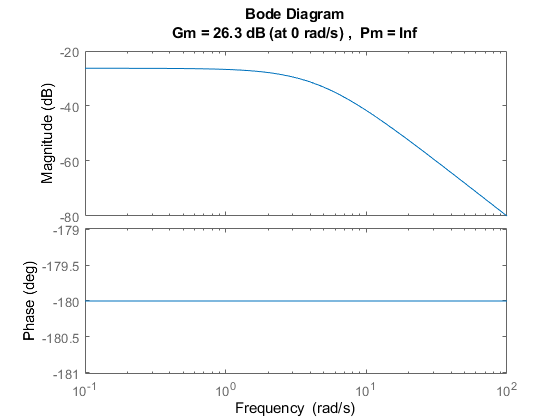

margin(plant);

poles = pole(plant)

poles =     4.5388
   -4.5388


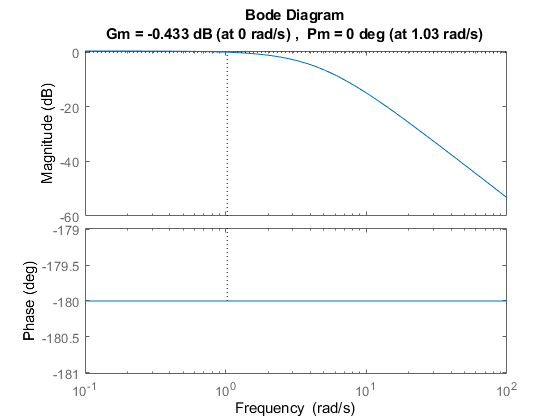


Kmin = 10^(26.3/20);
margin((Kmin + 1)*plant);

## Unity Feedback Analysis

disp("Unity Feedback Analysis ------------------------");

Unity Feedback Analysis ------------------------


unitySys = feedback(plant, 1)

unitySys =
 
      1
  ----------
  s^2 - 19.6
 
Continuous-time transfer function.



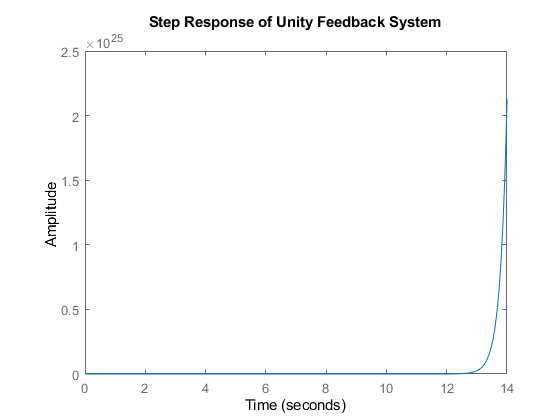

step(unitySys);
title("Step Response of Unity Feedback System");

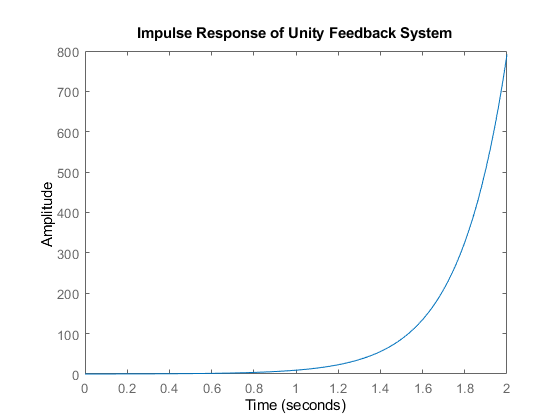

impulse(unitySys, 2);
title("Impulse Response of Unity Feedback System");

## Gain-Compensated w/ Unity Feedback Analysis

disp("Gain-Compensated w/ Unity Feedback Analysis-------------------");

Gain-Compensated w/ Unity Feedback Analysis-------------------


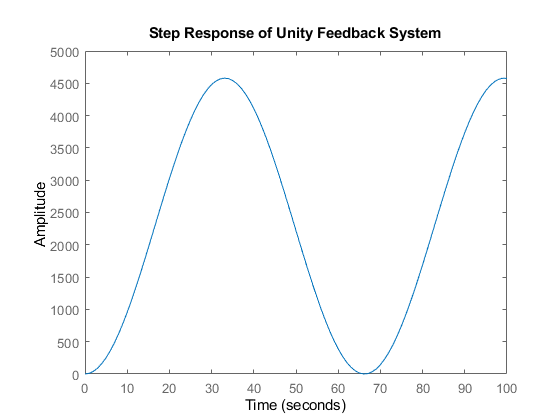


gain = 20.61;
gainCompUnitySys = feedback(plant*gain, 1);

step(gainCompUnitySys, 100);
title("Step Response of Unity Feedback System");

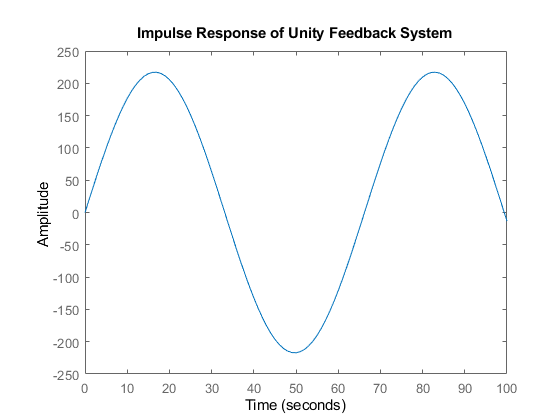


impulse(gainCompUnitySys, 100);
title("Impulse Response of Unity Feedback System");

## PID Controller w/ Unity Feedback Analysis

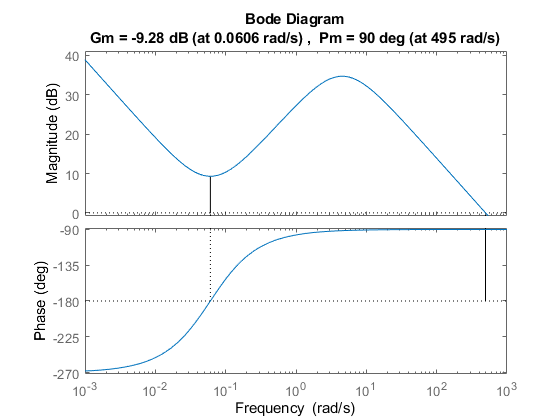

Kcr = 100; % Critical gain value
Pcr = 66; % Critical period

% Using Zuegler-Nichols Rules for PID
Kp = 0.6*Kcr;
Ti = 0.5*Pcr;
Td = 0.125*Pcr;
Gc = Kp*(1 + 1/(Ti*s) + Td*s);

PICompUnitySys= feedback(Gc*plant, 1);
margin(Gc*plant)

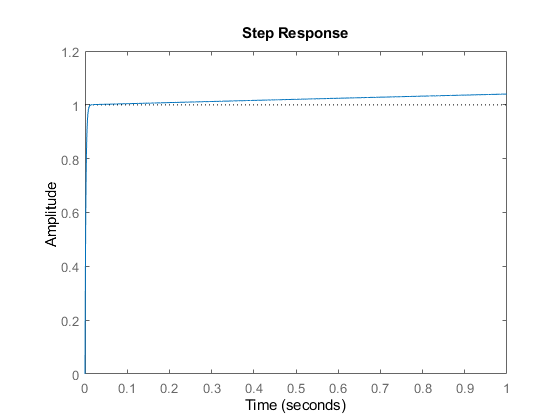

step(PICompUnitySys, 1);

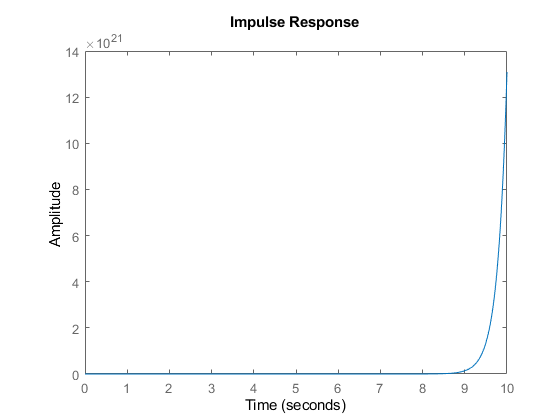

impulse(Gc*plant, 10);